# Lab 2: Övningar med Euler/Laplace och z-transform

4.

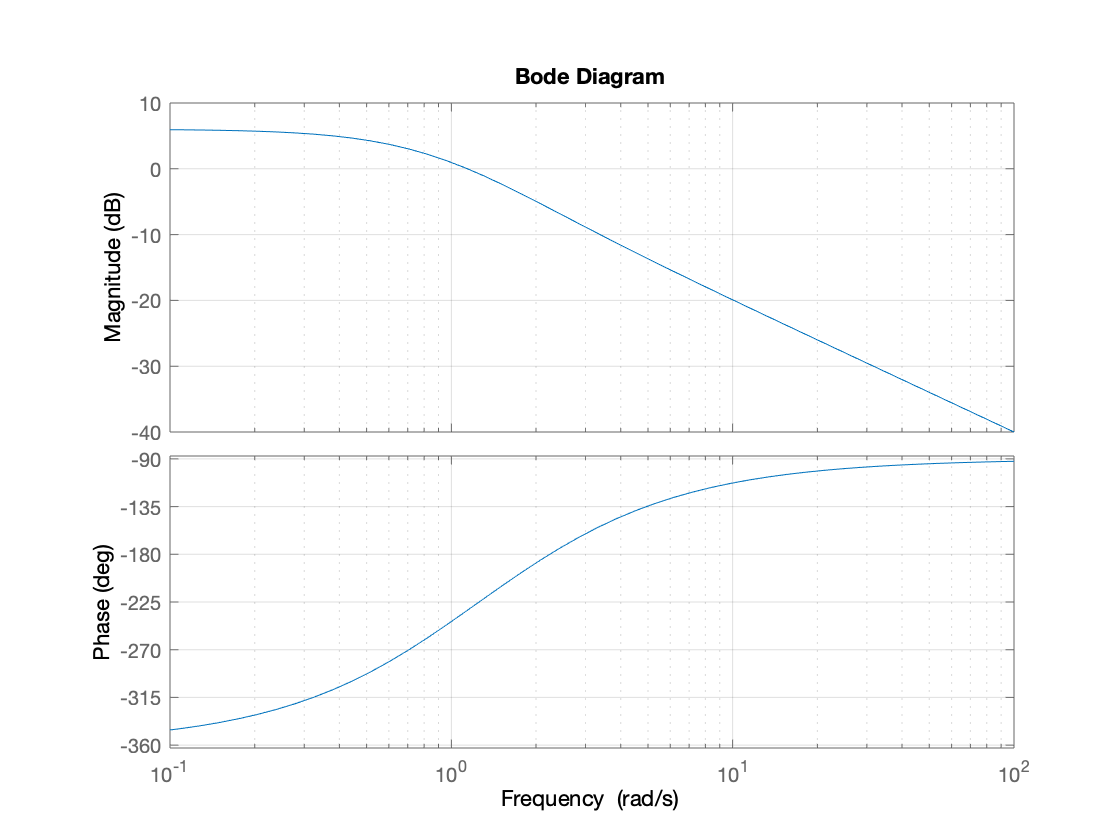

num = [0 1 2];
den = [1 -2 1];
bode(num,den);
grid on

7

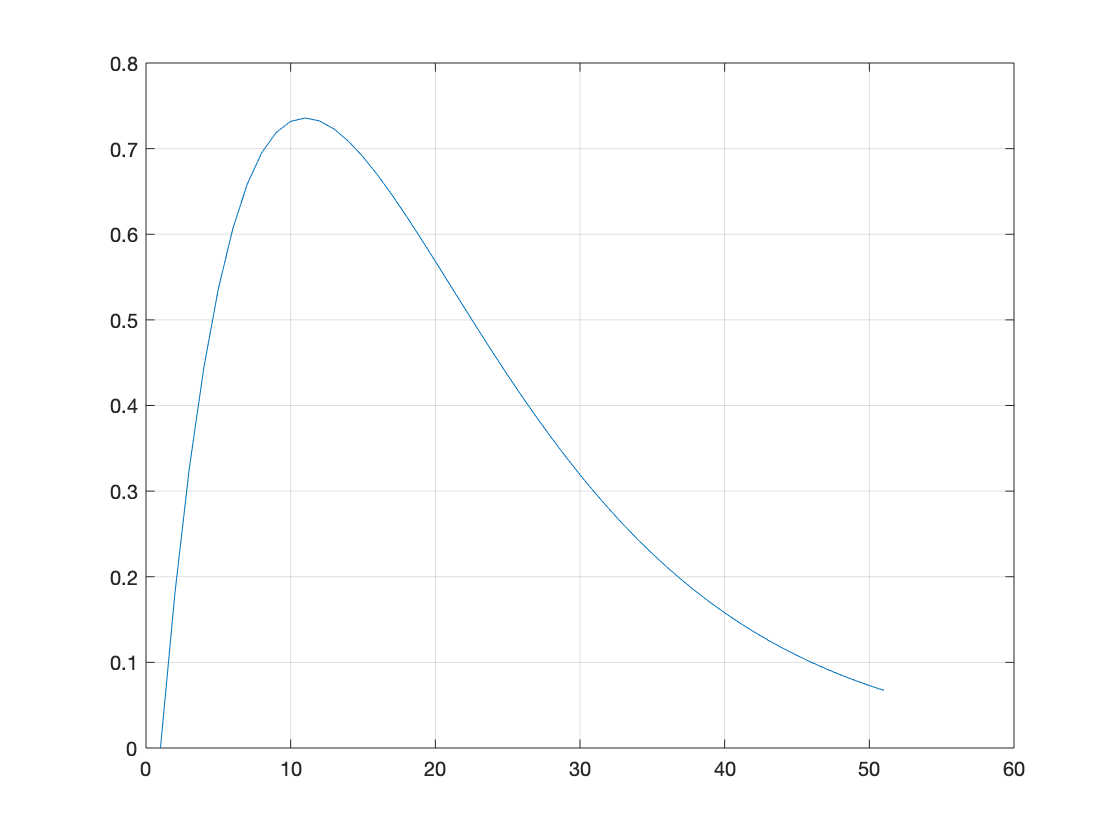

t=0:0.1:5;
y=2.*t.*exp(-t);
figure (1); plot(y); grid;

8

%50 st värden
N = 50;

%Vår insignal
x=exp(-t)

x =     1.0000    0.9048    0.8187    0.7408    0.6703    0.6065    0.5488    0.4966    0.4493    0.4066    0.3679    0.3329    0.3012    0.2725    0.2466    0.2231    0.2019    0.1827    0.1653    0.1496    0.1353    0.1225    0.1108    0.1003    0.0907    0.0821    0.0743    0.0672    0.0608    0.0550    0.0498    0.0450    0.0408    0.0369    0.0334    0.0302    0.0273    0.0247    0.0224    0.0202    0.0183    0.0166    0.0150    0.0136    0.0123    0.0111    0.0101    0.0091    0.0082    0.0074


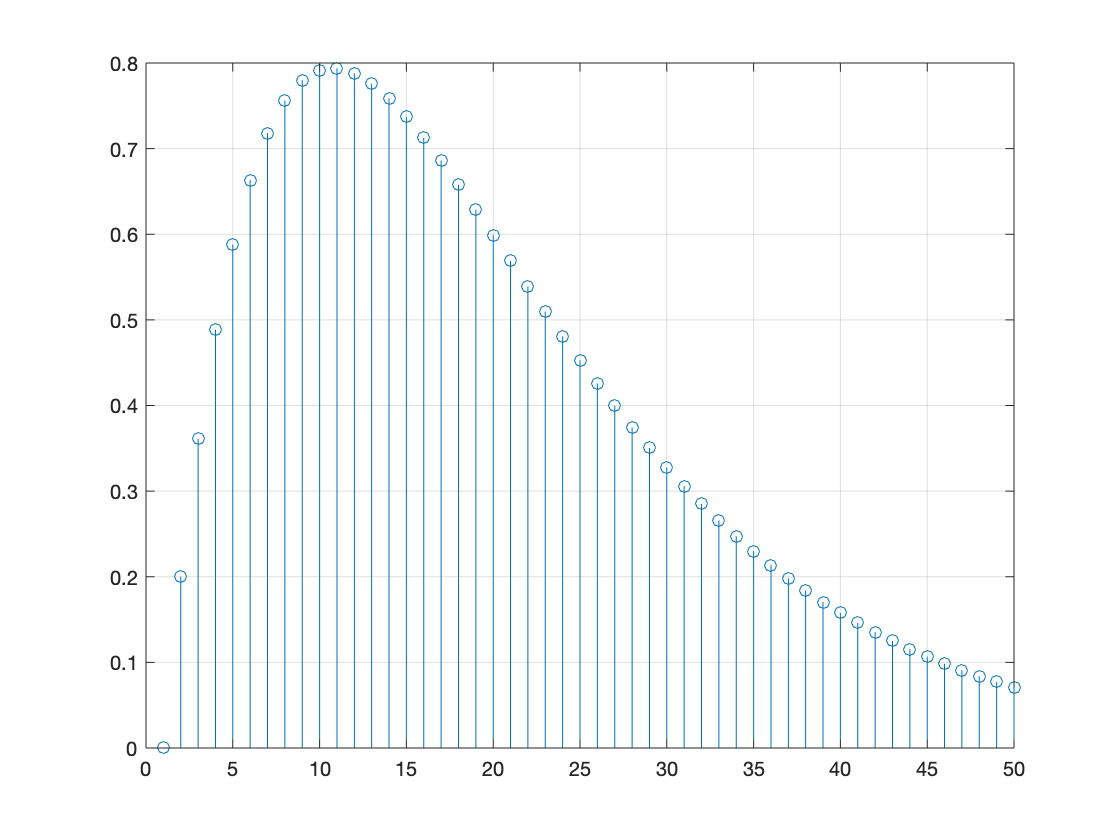


for m=2:N
    y(m)=0.9*y(m-1)+0.2*x(m-1);
end

%Rita resultatet
figure(2); stem(y); grid; xlim([0 50]);

9

%Exakt samma kod som för uppg 8 eftersom den har samma utsignal som uppg 7. 

10.

Ts=0.1

Ts = 0.1000

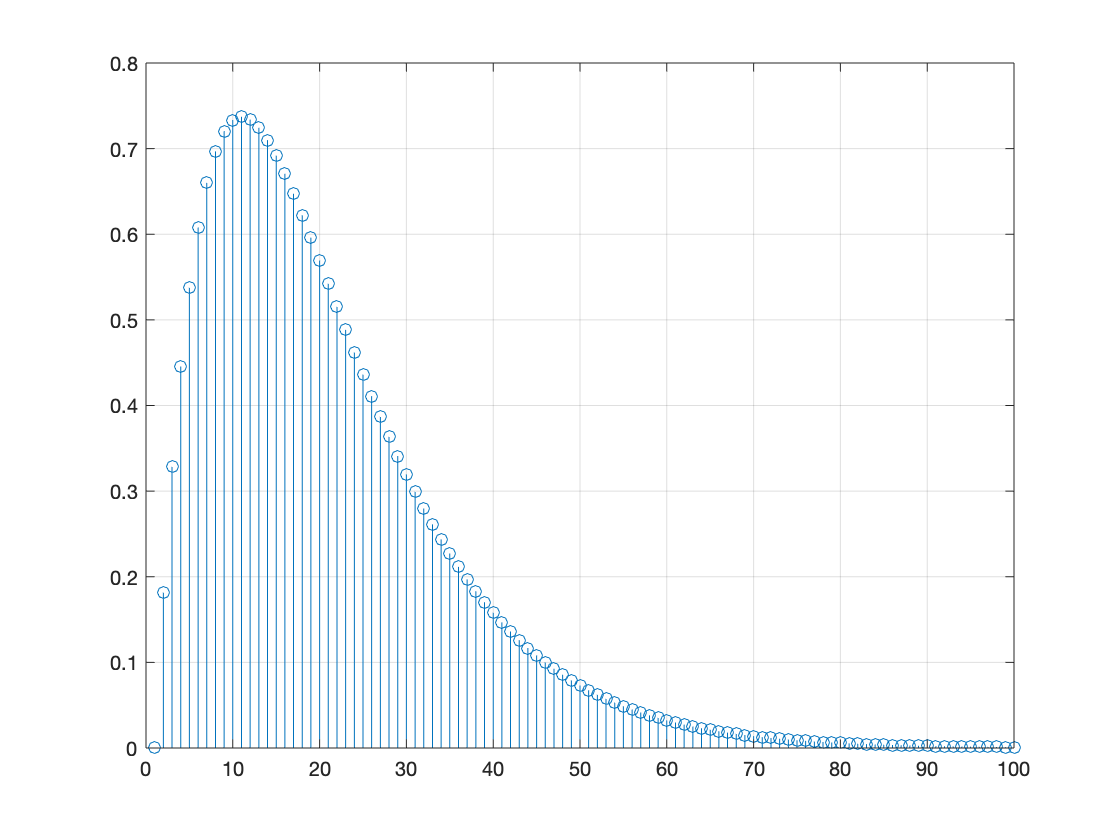

t=0:Ts:10;
x=exp(-t);
y=zeros(1,100);


for m=2:100
    y(m)=(0.2*x(m)+0.2*x(m-1)+1.9*y(m-1))/2.1;
end

figure(3); stem(y); grid; xlim([0 100]);

11.

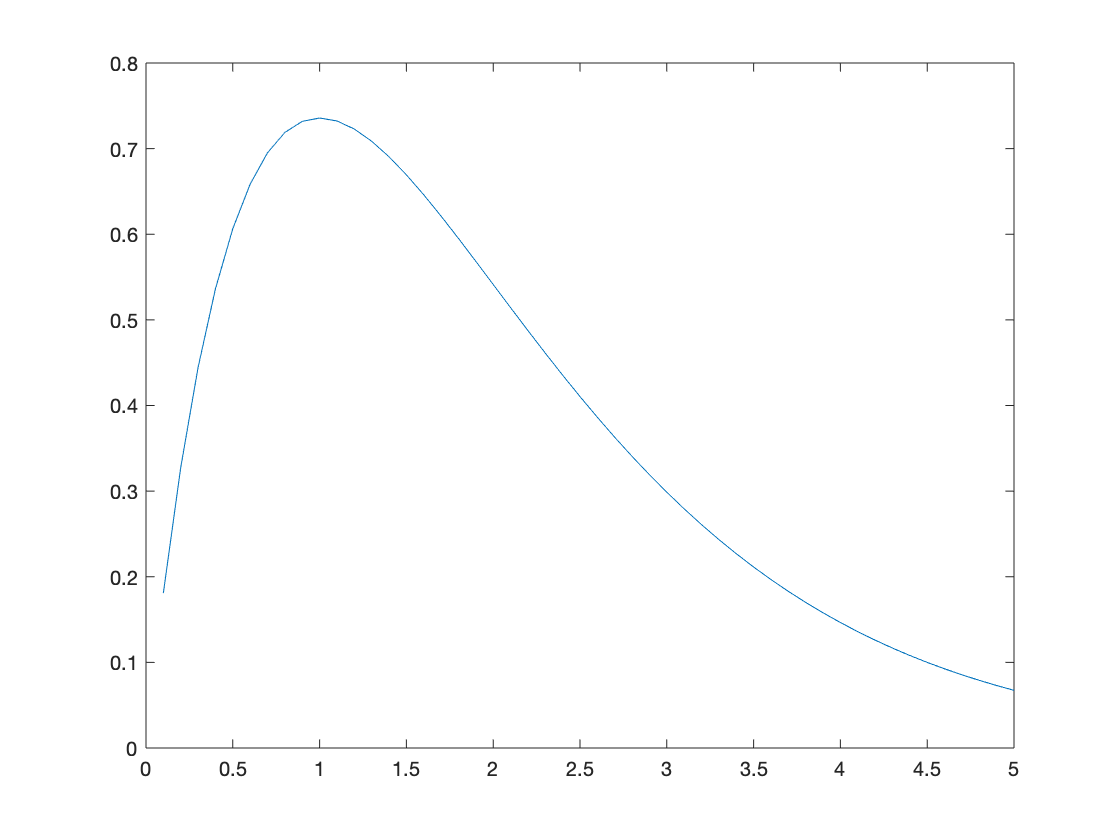

syms s;
Y = 2/(s+1)^2;
y = ilaplace(Y);

for n = 1:1:50
    t = 0.1*n;              %skapa t-värde
    y_numerisk(n)=eval(y);  %funk. "eval" uttnytjar t-värdet
    t2(n) = t;              %spara t-värde
end

plot(t2, y_numerisk);       %Rita graf